clc,clear
x=load('changgui.txt');
%%  第二步：判断是否需要正向化
[n,m] = size(x);
disp(['共有' num2str(n) '个评价对象, ' num2str(m) '个评价指标']) 

共有12个评价对象, 7个评价指标


Judge = input(['这' num2str(m) '个指标是否需要经过正向化处理，需要请输入1 ，不需要输入0：  ']);

if Judge == 1
    Position = input('请输入需要正向化处理的指标所在的列，例如第2、3、6三列需要处理，那么你需要输入[2,3,6]： '); %[2,3,4]
    disp('请输入需要处理的这些列的指标类型（1：极小型， 2：中间型， 3：区间型） ')
    Type = input('例如：第2列是极小型，第3列是区间型，第6列是中间型，就输入[1,3,2]：  '); %[2,1,3]
    % 注意，Position和Type是两个同维度的行向量
    for i = 1 : size(Position,2)  %这里需要对这些列分别处理，因此我们需要知道一共要处理的次数，即循环的次数
        x(:,Position(i)) = Positivization(x(:,Position(i)),Type(i),Position(i));
    % Positivization是我们自己定义的函数，其作用是进行正向化，其一共接收三个参数
    % 第一个参数是要正向化处理的那一列向量 X(:,Position(i))   回顾上一讲的知识，X(:,n)表示取第n列的全部元素
    % 第二个参数是对应的这一列的指标类型（1：极小型， 2：中间型， 3：区间型）
    % 第三个参数是告诉函数我们正在处理的是原始矩阵中的哪一列
    % 该函数有一个返回值，它返回正向化之后的指标，我们可以将其直接赋值给我们原始要处理的那一列向量
    end
    disp('正向化后的矩阵 X =  ')
    disp(x)
end

请输入需要处理的这些列的指标类型（1：极小型， 2：中间型， 3：区间型） 


第7列是极小型，正在正向化
第7列极小型正向化处理完成
~~~~~~~~~~~~~~~~~~~~分界线~~~~~~~~~~~~~~~~~~~~


正向化后的矩阵 X =  


   19.5000    0.6186   12.0000    1.6000    1.3000    1.1000    1.3000
   21.1000    0.7455    7.6000    1.0000    0.6000    0.6000    2.2000
   18.6000    0.5543   10.3000    3.0000    1.2000    0.9000    1.9000
   14.8000    0.6842    9.0000    2.5000    1.1000    2.5000    1.8000
   19.1000    0.5568    4.7000    9.2000    1.3000         0    0.8000
   17.0000    0.6182    6.9000    3.1000    1.5000    0.5000    2.0000
   17.8000    0.5730    8.4000    1.7000    0.8000    1.6000    1.3000
   14.6000    0.6567    7.9000    2.9000    0.4000    0.6000    2.1000
   11.4000    0.6636    9.4000    1.8000    0.6000    0.9000    2.0000
   16.2000    0.6039    5.6000    3.2000    1.3000    0.4000    1.9000
   16.6000    0.5172    3.2000    8.8000    1.9000    0.3000         0
   12.2000    0.6612    8.7000    1.0000    0.7000    1.6000    2.2000



%%  第三步：因子分析
x=zscore(x); %数据标准化 
r=cov(x) %求标准化数据的协方差阵，即求相关系数矩阵 

r =     1.0000   -0.1802   -0.0619    0.1915    0.3159   -0.3341   -0.2779
   -0.1802    1.0000    0.3851   -0.6865   -0.6914    0.3564    0.7428
   -0.0619    0.3851    1.0000   -0.7677   -0.4479    0.5801    0.5299
    0.1915   -0.6865   -0.7677    1.0000    0.6463   -0.5669   -0.8112
    0.3159   -0.6914   -0.4479    0.6463    1.0000   -0.2958   -0.6907
   -0.3341    0.3564    0.5801   -0.5669   -0.2958    1.0000    0.2948
   -0.2779    0.7428    0.5299   -0.8112   -0.6907    0.2948    1.0000



[M, lambda] = eig(r) %求r矩阵特征向量及特征值

M =     0.0960   -0.2322    0.1224    0.2532   -0.2988   -0.8579   -0.1800
   -0.0208    0.5601   -0.1534    0.6036    0.3122   -0.1914    0.4048
    0.2189    0.5285    0.1442   -0.4645   -0.5289   -0.1293    0.3739
    0.7809    0.2463    0.2300    0.1349    0.1507    0.1385   -0.4654
   -0.0204    0.2194   -0.8086    0.0622   -0.3606    0.0511   -0.4014
    0.2121   -0.3206    0.0665    0.5276   -0.5557    0.4037    0.3124
    0.5359   -0.3761   -0.4791   -0.2352    0.2684   -0.1606    0.4343


lambda =     0.0989         0         0         0         0         0         0
         0    0.1628         0         0         0         0         0
         0         0    0.3321         0         0         0         0
         0         0         0    0.4255         0         0         0
         0         0         0         0    0.9916         0         0
         0         0         0         0         0    1.0059         0
         0         0         0         0         0         0    3.9831


y1 = diag(lambda) %取出特征值矩阵中的特征值

y1 =     0.0989
    0.1628
    0.3321
    0.4255
    0.9916
    1.0059
    3.9831


size(x,2) %读取数据文件中的列数

ans = 7

x1 = [size(x,2):-1:1] %表示变量个数并倒写出它们作为x轴 如 4，3，2，1

x1 =      7     6     5     4     3     2     1


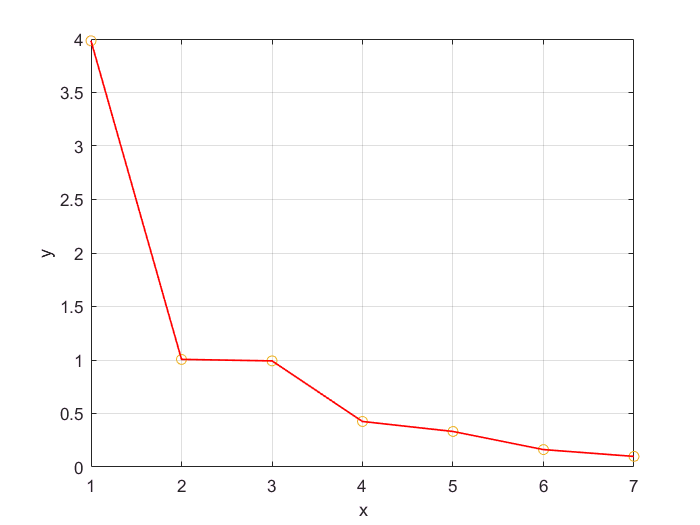

plot(x1,y1,'o') %绘制散点图
grid on %显示格线
hold on; %不换画布继续在这张画布上绘制
xlabel('x'); %x轴名称
ylabel('y'); %y轴名称
plot(x1,y1,'-','Color','r','lineWidth',1); %绘制折线图


[vec,val,con]=pcacov(r) %进行主成分分析的相关计算 

vec =     0.1800    0.8579    0.2988    0.2532   -0.1224   -0.2322    0.0960
   -0.4048    0.1914   -0.3122    0.6036    0.1534    0.5601   -0.0208
   -0.3739    0.1293    0.5289   -0.4645   -0.1442    0.5285    0.2189
    0.4654   -0.1385   -0.1507    0.1349   -0.2300    0.2463    0.7809
    0.4014   -0.0511    0.3606    0.0622    0.8086    0.2194   -0.0204
   -0.3124   -0.4037    0.5557    0.5276   -0.0665   -0.3206    0.2121
   -0.4343    0.1606   -0.2684   -0.2352    0.4791   -0.3761    0.5359


val =     3.9831
    1.0059
    0.9916
    0.4255
    0.3321
    0.1628
    0.0989


con =    56.9021
   14.3700
   14.1659
    6.0788
    4.7444
    2.3255
    1.4134


num=input('请选择主因子的个数：'); %交互式选择主因子的个数 
f1=repmat(sign(sum(vec)),size(vec,1),1); 
vec=vec.*f1; %特征向量正负号转换 
f2=repmat(sqrt(val)',size(vec,1),1); 
a=vec.*f2 %求初等载荷矩阵 

a =    -0.3593    0.8605    0.2975    0.1652   -0.0706   -0.0937    0.0302
    0.8078    0.1919   -0.3109    0.3938    0.0884    0.2260   -0.0066
    0.7463    0.1297    0.5266   -0.3030   -0.0831    0.2132    0.0689
   -0.9288   -0.1390   -0.1500    0.0880   -0.1326    0.0994    0.2456
   -0.8011   -0.0513    0.3591    0.0406    0.4660    0.0885   -0.0064
    0.6235   -0.4049    0.5534    0.3442   -0.0383   -0.1294    0.0667
    0.8668    0.1611   -0.2672   -0.1534    0.2761   -0.1517    0.1686


%如果指标变量多，选取的主因子个数少，可以直接使用factoran进行因子分析 
%本题中4个指标变量，选取2个主因子，factoran无法实现 
am=a(:,1:num) %提出num个主因子的载荷矩阵 
[b,t]=rotatefactors(am,'method', 'varimax') %旋转变换,b为旋转后的载荷阵 

b =    -0.1633    0.9613   -0.0856
    0.8664   -0.0635    0.1771
    0.3758    0.1380    0.8312
   -0.7148   -0.0009   -0.6274
   -0.8403    0.2082   -0.1544
    0.0929   -0.3318    0.8603
    0.8820   -0.0904    0.2504


t =     0.8030   -0.1870    0.5659
    0.3195    0.9366   -0.1439
   -0.5031    0.2964    0.8118


bt=[b,a(:,num+1:end)]; %旋转后全部因子的载荷矩阵 
contr=sum(bt.^2) %计算因子贡献 

contr =     2.9221    1.1088    1.9498    0.4255    0.3321    0.1628    0.0989


rate=contr(1:num)/sum(contr) %计算因子贡献率

rate =     0.4174    0.1584    0.2785


gong=cumsum(con) %求累积贡献率

gong =    56.9021
   71.2721
   85.4380
   91.5167
   96.2611
   98.5866
  100.0000



coef=inv(r)*b %计算得分函数的系数

coef =     0.0499    0.9070    0.0694
    0.3815    0.0479   -0.1672
   -0.0755    0.2431    0.5186
   -0.1553   -0.1306   -0.2349
   -0.3600    0.0972    0.1875
   -0.2837   -0.2409    0.5995
    0.3615    0.0294   -0.1187


score=x*coef %计算各个因子的得分

score =    -0.4463    1.3781    1.4305
    1.7606    1.6163   -0.6309
   -0.3775    0.8902    0.7735
   -0.2332   -0.8766    1.4668
   -0.8407    0.4811   -1.4734
    0.0438    0.3070   -0.3951
   -0.4342    0.1717    0.9526
    1.1196   -0.5709   -0.7205
    0.7812   -1.4200   -0.0411
    0.1300   -0.0994   -0.8150


weight=rate/sum(rate) %计算得分的权重

weight =     0.4886    0.1854    0.3260


Tscore=score*weight' %对各因子的得分进行加权求和，即求各球员综合得分

Tscore =     0.5038
    0.9541
    0.2328
    0.2018
   -0.8019
   -0.0505
    0.1303
    0.2063
    0.1051
   -0.2206


[STscore,ind]=sort(Tscore,'descend') %对球员进行排序

STscore =     0.9541
    0.5038
    0.2328
    0.2063
    0.2018
    0.1923
    0.1303
    0.1051
   -0.0505
   -0.2206


ind =      2
     1
     3
     8
     4
    12
     7
     9
     6
    10


display=[score(ind,:)';STscore';ind'] %显示排序结果

display =     1.7606   -0.4463   -0.3775    1.1196   -0.2332    0.5893   -0.4342    0.7812    0.0438    0.1300   -0.8407   -2.0926
    1.6163    1.3781    0.8902   -0.5709   -0.8766   -1.4172    0.1717   -1.4200    0.3070   -0.0994    0.4811   -0.4603
   -0.6309    1.4305    0.7735   -0.7205    1.4668    0.5126    0.9526   -0.0411   -0.3951   -0.8150   -1.4734   -1.0600
    0.9541    0.5038    0.2328    0.2063    0.2018    0.1923    0.1303    0.1051   -0.0505   -0.2206   -0.8019   -1.4533
    2.0000    1.0000    3.0000    8.0000    4.0000   12.0000    7.0000    9.0000    6.0000   10.0000    5.0000   11.0000
